Kattints az út rajzolásához! Nyomj ENTER-t a záráshoz.
Számolás: Pálya generálás...


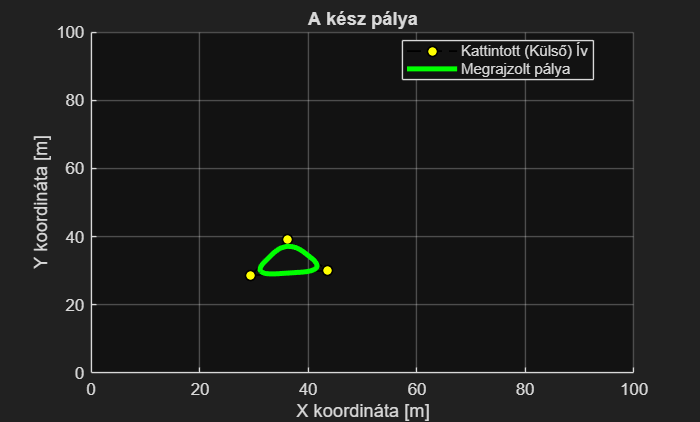

%% ============================================================
%  MAIN SCRIPT
%  ------------------------------------------------------------
%  Project name   : Tube MPC optimization with neural network
%  Author         : Bene Ádám
%  Date           : 2026.04.28.
%  Description    : Main execution script that calls the
%                   required submodules and processing steps.
%
%  Note           : Run this file directly.
%% ============================================================

% reference path define for the controller
run("path_define.mlx")

=== 2. FÁZIS: CasADi MPC Szimuláció és Adatgyűjtés ===
CasADi szimuláció fut... (az IPOPT megoldó dolgozik)
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  29.00us (  3.62us)         8
       nlp_g  |        0 (       0)  56.00us (  7.00us)         8
  nlp_grad_f  |        0 (       0)  36.00us (  4.00us)         9
  nlp_hess_l  |        0 (       0)  19.00us (  2.71us)         7
   nlp_jac_g  |        0 (       0)  33.00us (  3.67us)         9
       total  |   1.23 s (  1.23 s)   1.23 s (  1.23 s)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  31.00us (  3.87us)         8
       nlp_g  |        0 (       0)  75.00us (  9.37us)         8
  nlp_grad_f  |        0 (       0)  45.00us (  5.00us)         9
  nlp_hess_l  |        0 (       0)  19.00us (  2.71us)         7
   nlp_jac_g  |        0 (       0)  42.00us (  4.67us)         9
       total  |  42.00ms ( 42.00ms

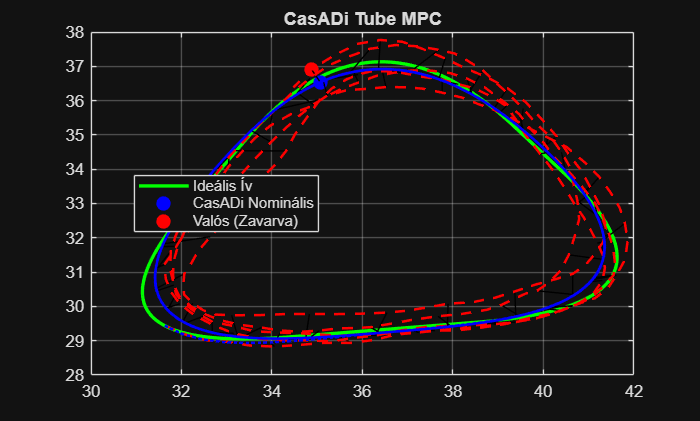


% run tube MPC for previously defined reference path
run("tube_mpc.mlx")

=== Neurális Háló Tanítása Indul ===


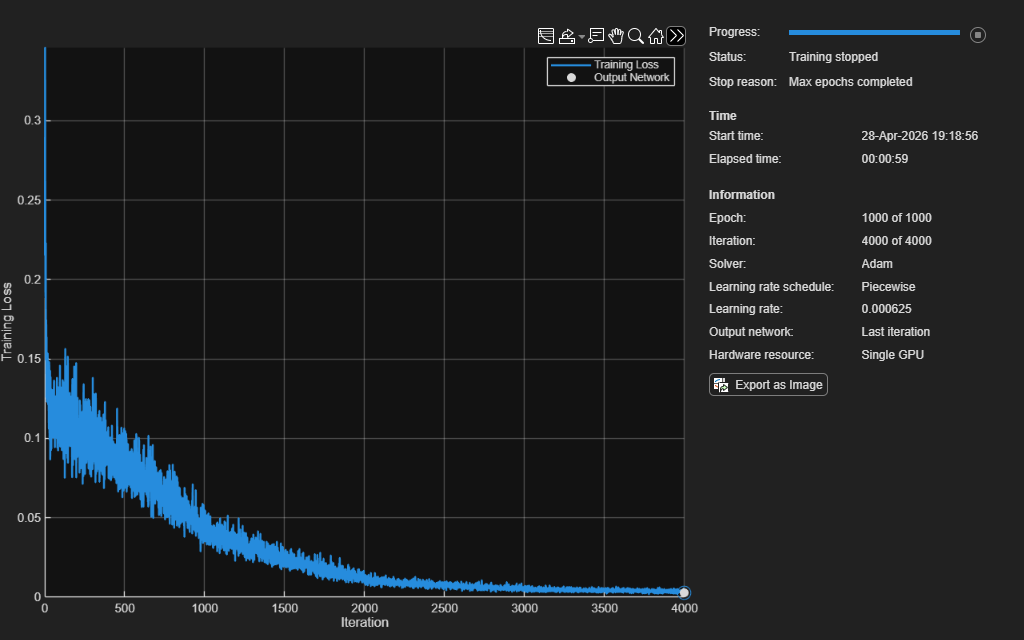

=== TANÍTÁS BEFEJEZŐDÖTT! A "net" nevű objektum elkészült. ===
--- Tesztelés az első időlépésen ---
Valós maradék hiba (a szimulációdból):
         0         0    0.6339   -0.1049

Neurális háló által becsült hiba:
    0.0003    0.0043    0.6433   -0.1205




% train the NN from the offline data of the previous simulation
run("train_nn.mlx")